clear
% flags
showplot = true;
saveplot = false;

subject = "0d5e8e"; % single subject
data_pre = "EP_Measure-3.mat"; % not really "pre" because no conditioning
data_post = "EP_Measure-4.mat"; % not really "post" because no conditioning

windows = [ [-0.02,1.5]; [-.5,1]; [-0.02,.05]; [-0.02,.02]; [-0.02,.2]; [-0.02,.5] ]; % 1s or 20,50,200,500ms after stim onset
isfilt = true;
compare = false;
window_time = windows(1,:);
% for comparing unfiltered (raw or art_rem) vs filtered (filt) data
% [fs, response_pre, avgresponse_pre, mainchans_pre] = extractEPs_single(subject,data_post,window_time,"raw");
% [fs, response_post, avgresponse_post, mainchans_post] = extractEPs_single(subject,data_post,window_time,"filt");

% for comparing pre vs post average responses
if isfilt
    [fs, response_pre, avgresponse_pre, mainchans_pre] = extractEPs_single(subject,data_pre,window_time,"filt");
    [fs, response_post, avgresponse_post, mainchans_post] = extractEPs_single(subject,data_post,window_time,"filt2");
else
    [fs, response_pre, avgresponse_pre, mainchans_pre] = extractEPs_single(subject,data_pre,window_time,"artrem");
    [fs, response_post, avgresponse_post, mainchans_post] = extractEPs_single(subject,data_post,window_time,"artrem");
end

N_chan = size(avgresponse_pre,2);
N_pair = size(avgresponse_pre,1);
window_sz = length(avgresponse_pre);

if compare
    %chans_pre = 17:26; chans_post = 1:10;
    chans_pre = 27:36; chans_post = 11:20;
    if showplot
        f = figure();
    else
        f = figure('Visible','off');
    end
    f.Position(3)=f.Position(3)*2;
    
    for i=1:length(chans_pre)
        C_r_artrem = chans_pre(i);
        C_r_filt = chans_post(i);
        % subtract mean of 20ms period before stim onset (within channel)
        start = floor( (abs(window_time(1))-.02)*fs+1 );
        stop = start + floor(.02*fs);
        preEP = squeeze( avgresponse_pre(C_r_artrem,:) - mean(avgresponse_pre(C_r_artrem,start:stop)) );
        postEP = squeeze( avgresponse_post(C_r_filt,:) - mean(avgresponse_post(C_r_filt,start:stop)) );
            
        % plot pre vs post - comparing stim at one pair vs stim another pair
        subplot(2,length(chans_pre)/2,i)
        plot(linspace(window_time(1),window_time(2),window_sz),preEP,'b')
        hold on
        plot(linspace(window_time(1),window_time(2),window_sz),postEP,'r')
        if isequal(window_time,[-.5,1])
            xlim([window_time(1), window_time(2)])
        else
            xlim([0, window_time(2)])
        end
        ylim([-1e-3, 1e-3])
        title("Ch" + num2str(C_r_artrem))
        if C_r_artrem == chans_pre(end)
            legend('artrem','filt2')
        end
    end
    
    if saveplot
        %figName = "ch17-26_stim27_28_filt10_vs_artrem";
        figName = "ch27-36_stim23_24_filt10_vs_artrem";
        if ~isequal(window_time,[-.5,1])
            figName = figName+"_"+num2str(window_time(2)*1000)+"ms";
        end
        saveas(gcf,figName,'png')
    end
end

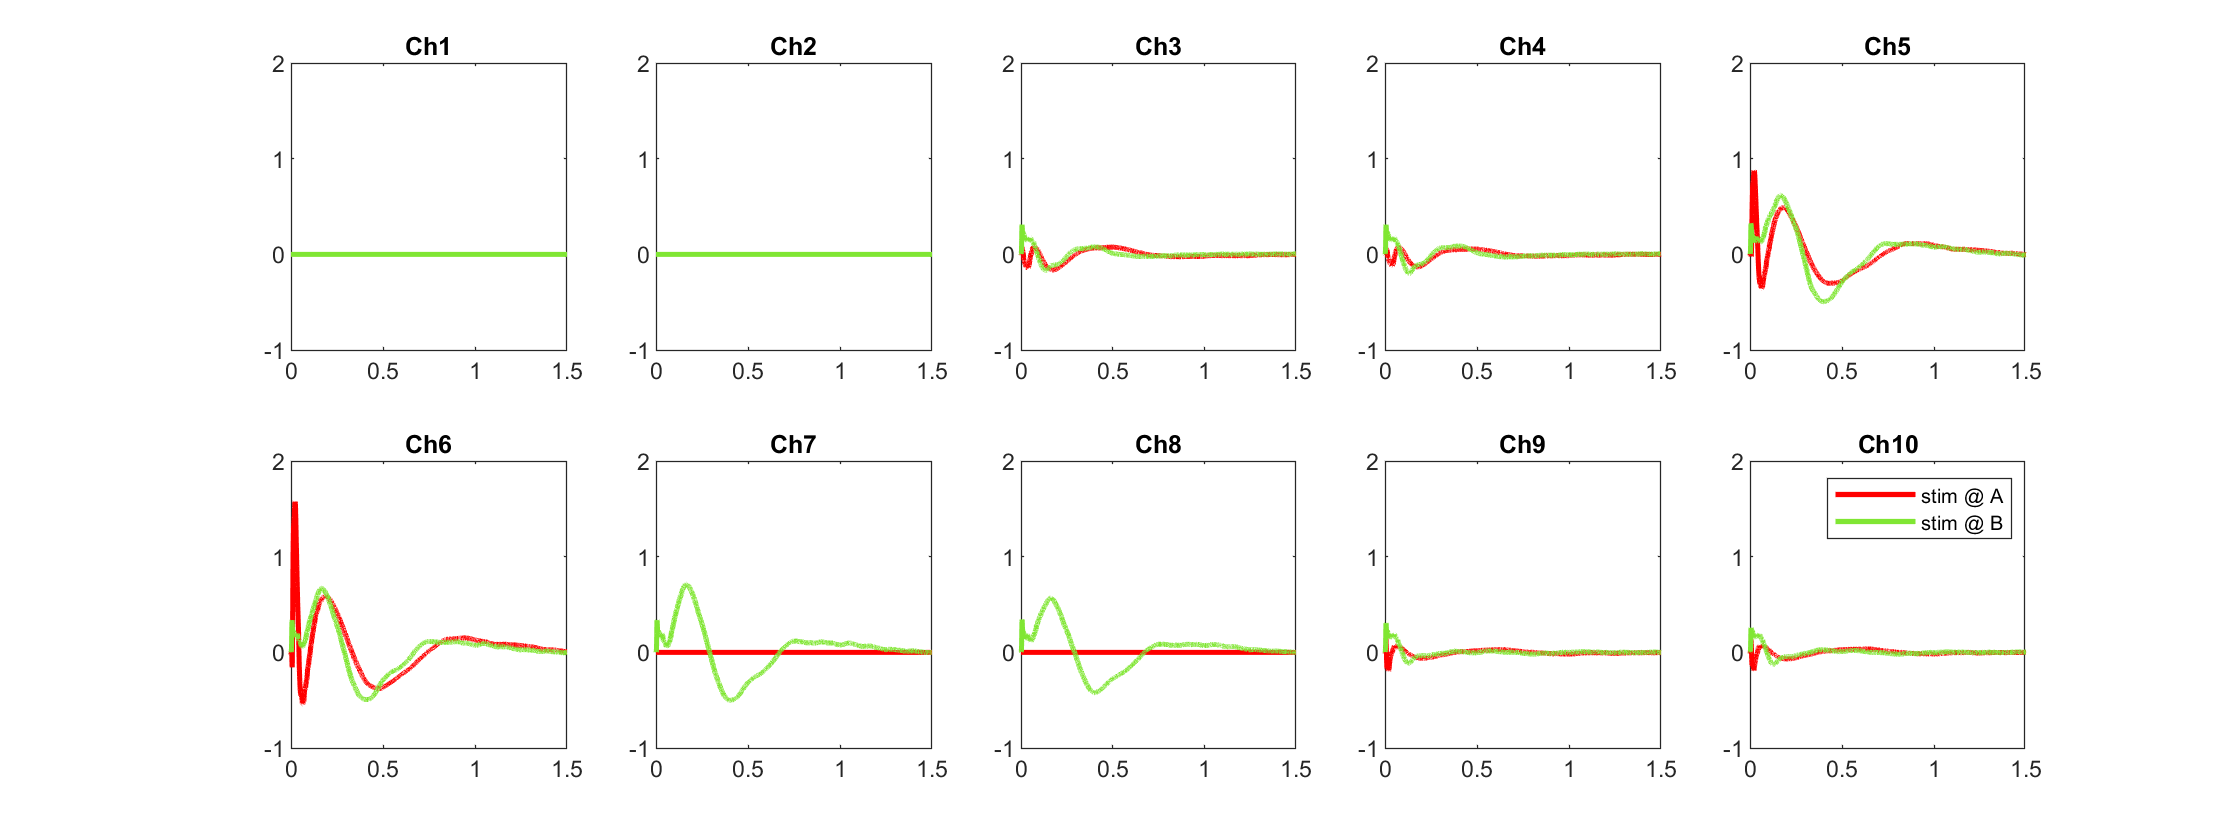

if isfilt
    chans_pre = 1:10; chans_post = 11:20;
else
    chans_pre = 17:26; chans_post = 27:36;
end
use_chans = chans_pre;
C_s = min(mainchans_pre);

if showplot
    f = figure();
else
    f = figure('Visible','off');
end
f.Position(3)=f.Position(3)*2;

for i=1:length(use_chans)
    C_r_idx = use_chans(i);
    if isfilt
        C_r = C_r_idx+17-1;
    else
        C_r = C_r_idx;
    end
    % subtract mean of 20ms period before stim onset (within channel)
    start = floor( (abs(window_time(1))-.02)*fs+1 );
    stop = start + floor(.02*fs);
    preEP = squeeze( avgresponse_pre(C_r_idx,:) - mean(avgresponse_pre(C_r_idx,start:stop)) );
    postEP = squeeze( avgresponse_post(C_r_idx,:) - mean(avgresponse_post(C_r_idx,start:stop)) );
        
    % plot pre vs post - comparing stim at one pair vs stim another pair
    subplot(2,length(use_chans)/2,i)
    plot(linspace(window_time(1),window_time(2),window_sz),preEP*1000,'r','LineWidth',2)
    hold on
    plot(linspace(window_time(1),window_time(2),window_sz),postEP*1000,'Color',[0.5 .9 0.2],'LineWidth',2)
    if isequal(window_time,[-.5,1])
        xlim([window_time(1), window_time(2)])
    else
        xlim([0, window_time(2)])
    end
    ylim([-1, 2])
    %ylim([-1e-3, 1e-3])
    title("Ch" + num2str(C_r_idx)) % C_r
    if C_r_idx == use_chans(end)
        legend('stim @ A','stim @ B')
        %legend('stim@23-24','stim@27-28')
    end
end


if saveplot
    cd('filt')
    figName = "ch17-26";
    if isfilt
        figName = figName+"_filt2";
    end
    if ~isequal(window_time,[-.5,1])
        figName = figName+"_"+num2str(window_time(2)*1000)+"ms";
    end
    saveas(gcf,figName,'png')
end

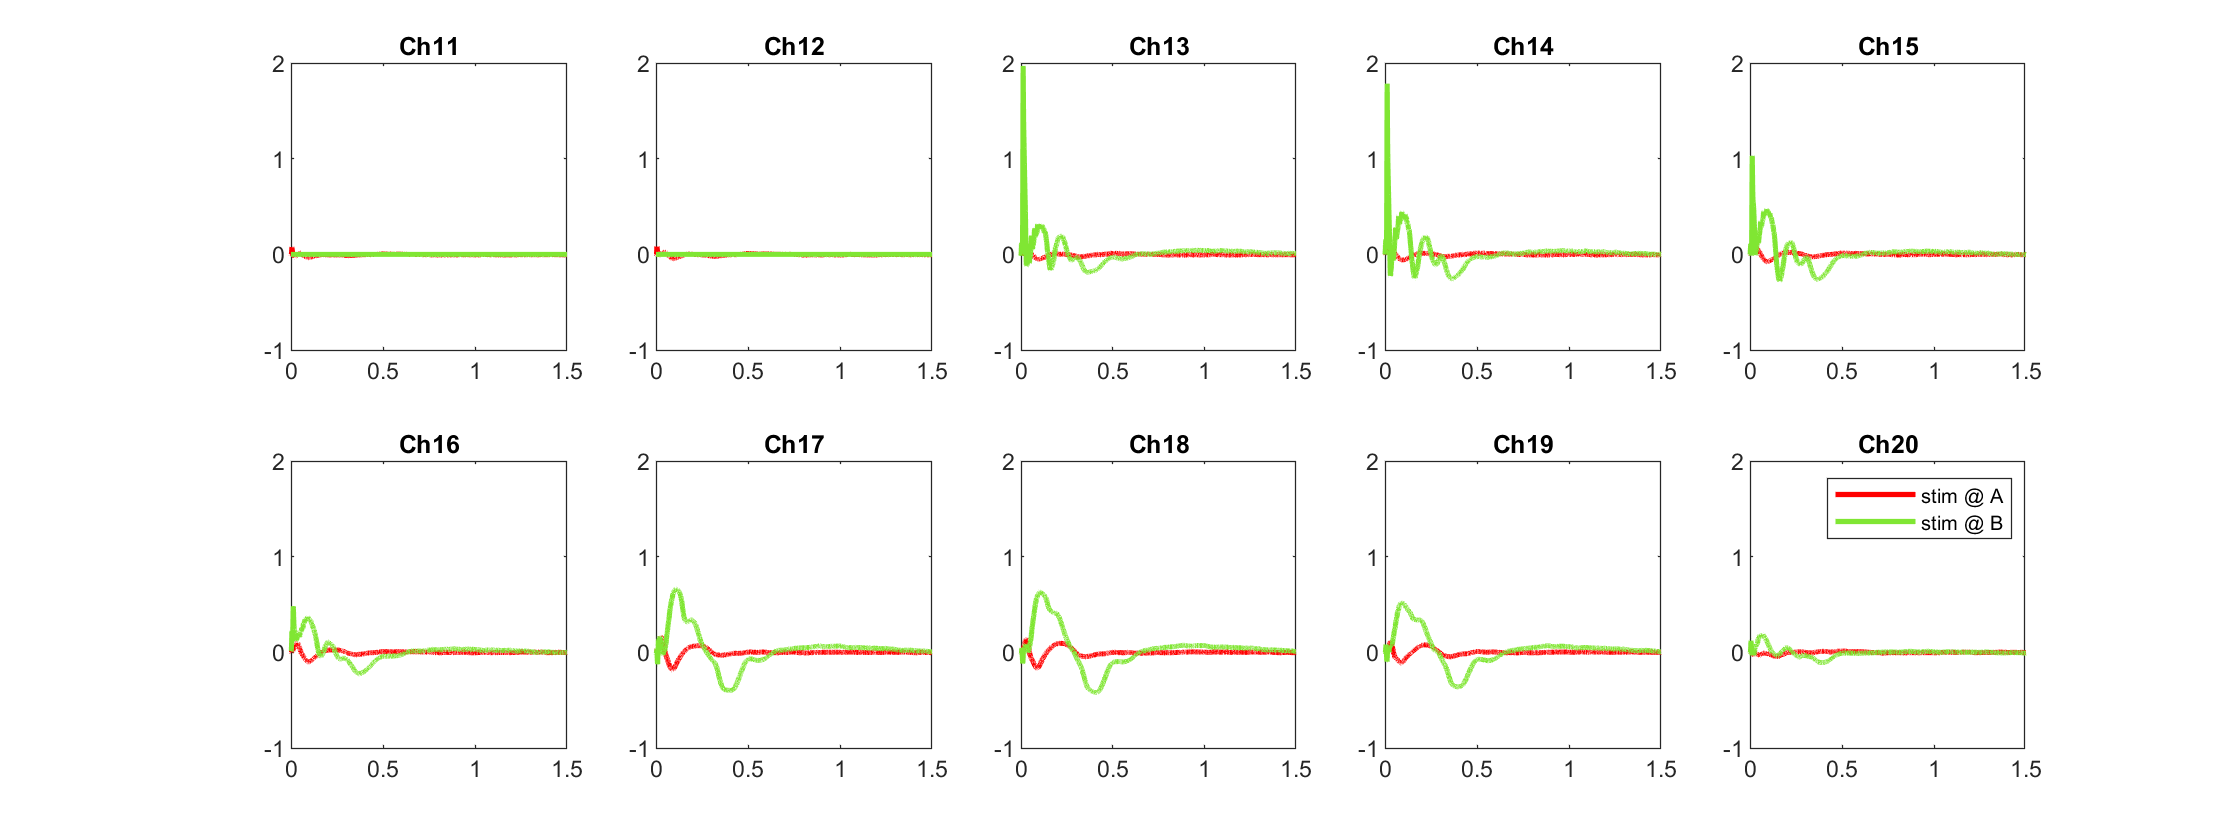

if isfilt
    chans_pre = 1:10; chans_post = 11:20;
else
    chans_pre = 17:26; chans_post = 27:36;
end
use_chans = chans_post;
C_s = min(mainchans_post);

if showplot
    f = figure();
else
    f = figure('Visible','off');
end
f.Position(3)=f.Position(3)*2;

for i=1:length(use_chans)
    C_r_idx = use_chans(i);
    if isfilt
        C_r = C_r_idx+17-1;
    else
        C_r = C_r_idx;
    end
    % subtract mean of 20ms period before stim onset (within channel)
    start = floor( (abs(window_time(1))-.02)*fs+1 );
    stop = start + floor(.02*fs);
    preEP = squeeze( avgresponse_pre(C_r_idx,:) - mean(avgresponse_pre(C_r_idx,start:stop)) );
    postEP = squeeze( avgresponse_post(C_r_idx,:) - mean(avgresponse_post(C_r_idx,start:stop)) );
        
    % plot pre vs post - comparing stim at one pair vs stim another pair
    subplot(2,length(use_chans)/2,i)
    plot(linspace(window_time(1),window_time(2),window_sz),preEP*1000,'r','LineWidth',2)
    hold on
    plot(linspace(window_time(1),window_time(2),window_sz),postEP*1000,'Color',[0.5 .9 0.2],'LineWidth',2)
    if isequal(window_time,[-.5,1])
        xlim([window_time(1), window_time(2)])
    else
        xlim([0, window_time(2)])
    end
    ylim([-1, 2])
    %ylim([-1e-3, 1e-3])
    title("Ch" + num2str(C_r_idx)) % C_r
    if C_r_idx == use_chans(end)
        legend('stim @ A','stim @ B')
        %legend('stim@23-24','stim@27-28')
    end
end


if saveplot
    figName = "ch27-36";
    if isfilt
        figName = figName+"_filt2";
    end
    if ~isequal(window_time,[-.5,1])
        figName = figName+"_"+num2str(window_time(2)*1000)+"ms";
    end
    saveas(gcf,figName,'png')
end